# 实验一 状态反馈与状态观测器

给定系统：

A=[-2 2 -1;0 -2 0;1 -1 0];
B=[-1;1;-1];
C=[1 -1 0];
D=0;
x0=[2;-1;1.6];
G=ss(A,B,C,D);

## 一、系统能控性和能观性

通过计算系统的能控性矩阵和能观性矩阵来判断系统是否可控、可观测，从而确定是否可以进行极点配置。

%计算能控性矩阵
Qc=ctrb(A,B);
%计算能观性矩阵
Qo=obsv(A,C);
%确定是否可控
if rank(Qc)==length(A)
    fprintf('system is Controlable, \nrank of controllability matrix is %d',rank(Qc))
end

system is Controlable, 
rank of controllability matrix is 3

%确定是否能观测
if rank(Qo)==length(A)
     fprintf('system is Observable, \nrank of observability matrix is %d',rank(Qo))
end

system is Observable, 
rank of observability matrix is 3

## 二、设计状态反馈控制器

`根据给出的性能指标要求，用极点配置的方法设计状态反馈控制器。可否通过状态反馈将系统极点配置在`-1+i`，`-2`和`-1-i`处？如可以，求出上述极点配置的反馈增益向量，并绘制零输入系统状态响应曲线；`

`(1) 由上节可知，该系统可控，可以通过状态反馈配置极点`

`(2) 确定极点配置的反馈增益向量`

P=[-1+1i;-2;-1-1i];
K=acker(A,B,P)

K =     3.0000    5.0000    2.0000


加入状态反馈之后系统的极点为（可以看出与要求的极点一致）

%获得增加状态反馈后的状态空间方程
A2=A-B*K;
G2=ss(A2,B,C,0);
[p,~]=pzmap(G2);
display(p)

p =   -2.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


(3) 绘制零输入系统状态响应曲线

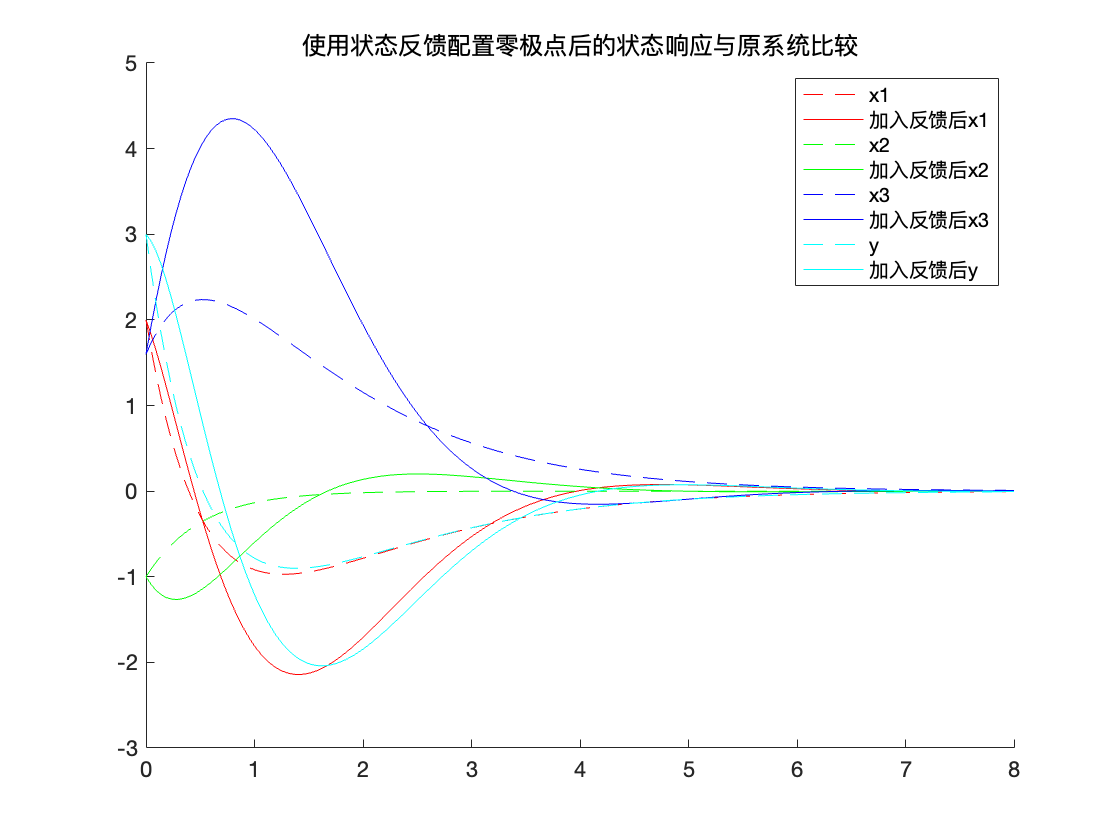

Tfinal=8;
[y,t,x]=initial(G,x0,Tfinal);
[y2,t2,x2]=initial(G2,x0,Tfinal);
figure();hold on;

label={'x1','x2','x3','y'};
specs={'r','g','b','c','b'};
for i=1:3
    plot(t,x(:,i),strcat(specs{i},'--'),'DisplayName',label{i})
    plot(t2,x2(:,i),specs{i},'DisplayName',strcat('加入反馈后',label{i}))
end
i=4;
    plot(t,y,strcat(specs{i},'--'),'DisplayName',label{i})
    plot(t2,y2,specs{i},'DisplayName',strcat('加入反馈后',label{i}))
legend;
hold off
title('使用状态反馈配置零极点后的状态响应与原系统比较')

## 三、设计全维状态观测器

3）根据状态观测器设计的要求，设计全维状态观测器，实现状态观测器的期望极点配置。若系统状态无法直接测量，可否通过状态观测器获取状态变量？若可以，设计一个极点位于-1，-2和-3处的全维状态观测器，并绘制在观测器初始状态为0时的零输入观测器状态响应曲线；

(1) 由一可知，系统可控，所以可以设计状态观测器

P3=[-1;-2;-3];
H=acker(A',C',P3);
H=H'

H =      2
     0
    -2


使用如下形式对系统进行建模，此时系统的极点与要求的极点一致，整个系统包含两次配置的所有极点


$$\left[\begin{array}{ccc}
\dot{x}\\
\dot{\hat{x}}
\end{array}\right]
=
\left[\begin{array}{ccc}
A & -BK\\
HC & A-HC-BK
\end{array}\right]
\left[\begin{array}{ccc}
x\\
\hat{x}
\end{array}\right]
+\left[\begin{array}{ccc}
B \\ B
\end{array}\right]
v
\\
y=\left[\begin{array}{ccc}
C & 0
\end{array}\right]
\left[\begin{array}{ccc}
x\\
\hat{x}
\end{array}\right]$$


%K=zeros(1,length(A));%K可以直接用上面求到的K
A3=[A,-B*K;H*C,A-H*C-B*K];
B3=[B;B];
C3=[C,zeros(1,length(A))];
D3=0;
G3=ss(A3,B3,C3,D3);
[p,~]=pzmap(G3)

p =   -3.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -1.0000 + 0.0000i
  -2.0000 + 0.0000i
  -2.0000 + 0.0000i


绘制系统状态与观测器状态的响应曲线，从曲线中，可以看出，观测器状态快速跟随目标系统状态

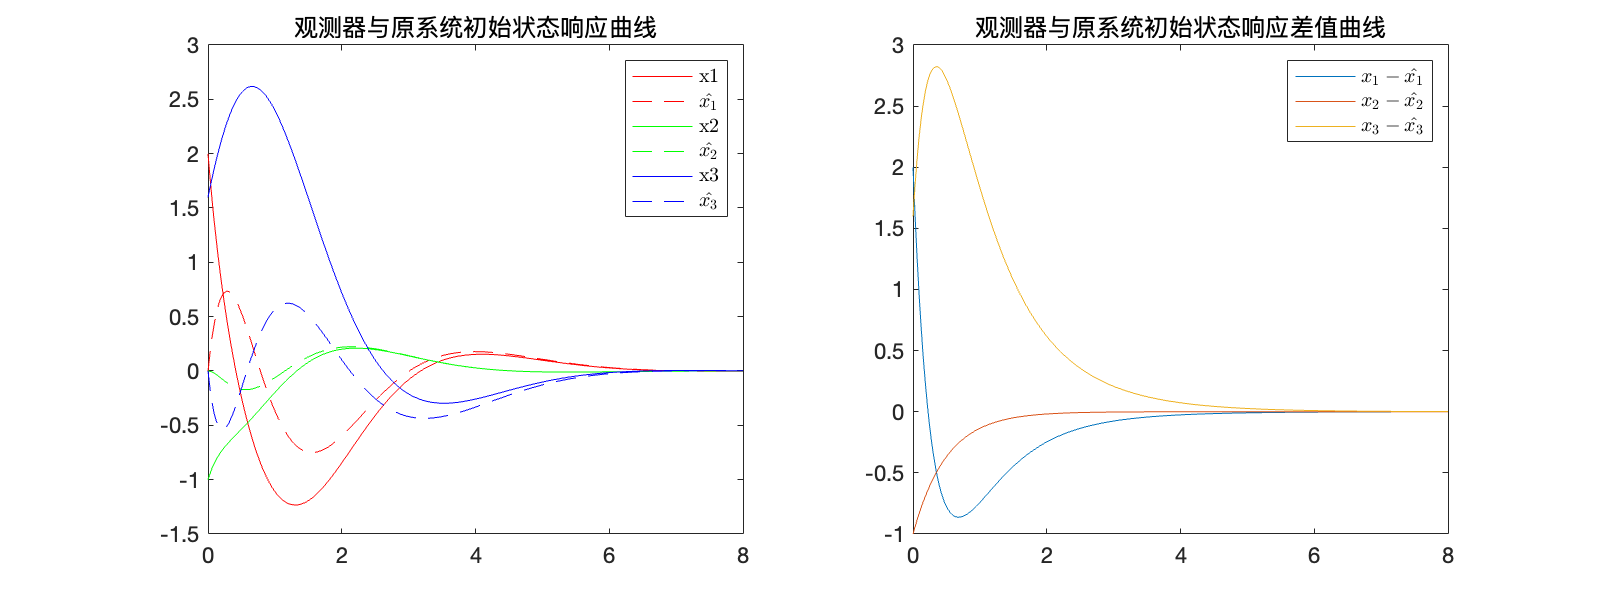

Tfinal=8;
[~,t3,x3]=initial(G3,[x0;zeros(size(x0))],Tfinal);
figure('Position',[0,0,800,300]);
subplot(1,2,1)
plot(t3,x3(:,1),'r', t3,x3(:,4),'r--',...
    t3,x3(:,2),'g', t3,x3(:,5),'g--',...
    t3,x3(:,3),'b', t3,x3(:,6),'b--');
legend({'x1','$\hat{x_1}$','x2','$\hat{x_2}$','x3','$\hat{x_3}$'},'Interpreter','latex');
title('观测器与原系统初始状态响应曲线');
subplot(1,2,2)
plot(t3,x3(:,1:3)-x3(:,4:6));
legend({'$x_1-\hat{x_1}$','$x_2-\hat{x_2}$','$x_3-\hat{x_3}$'},'Interpreter','latex');
title('观测器与原系统初始状态响应差值曲线')

## 四、分析实验结果

    综上，在加入状态反馈之后，系统的状态响应的快速性得到了很好的改善，但本实验中系统的超调有所增大。使用状态观测器之后，在零初始条件下，观测器状态与原系统一致，当含有初始状态时，观测器状态响应会跟随原系统状态，并逐渐趋于同步。

## 附：

### 加入状态观测器后零初始条件下的阶跃响应

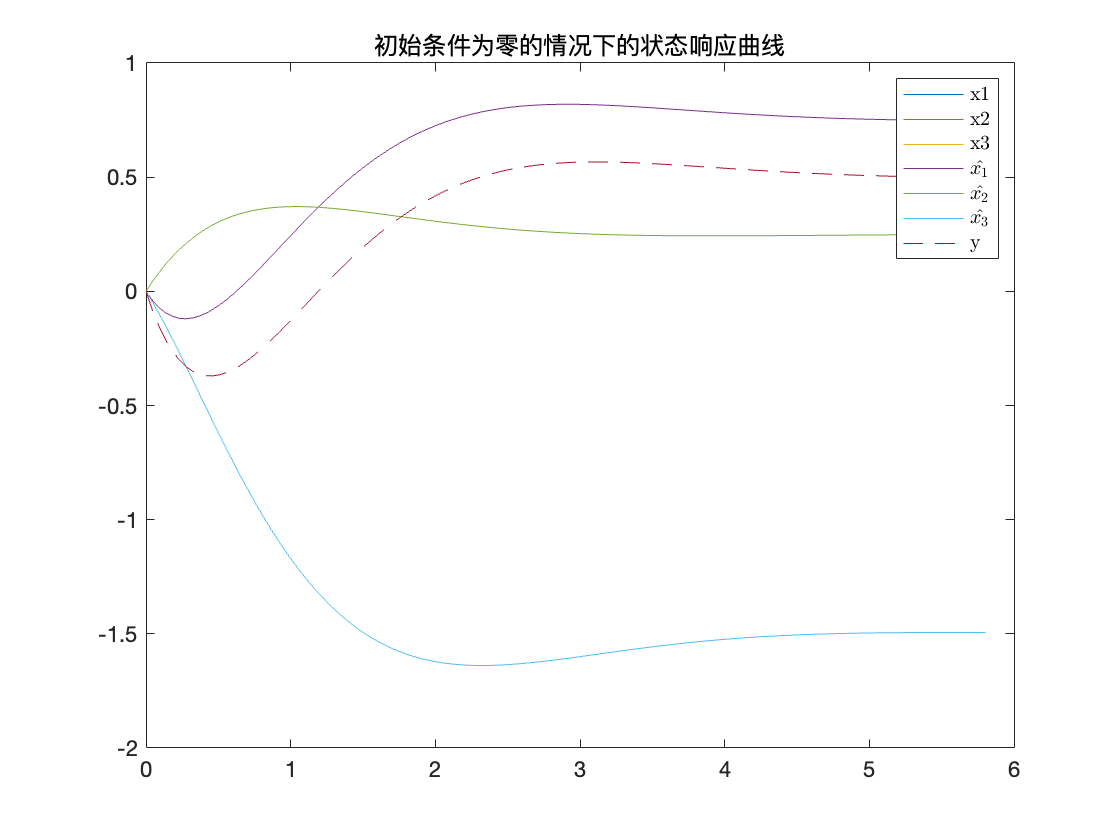

[y4,t4,x4]=step(G3);
figure();
plot(t4,x4,t4,y4,'--');
legend({'x1','x2','x3','$\hat{x_1}$','$\hat{x_2}$','$\hat{x_3}$','y'},'Interpreter','latex');
title('初始条件为零的情况下的状态响应曲线');